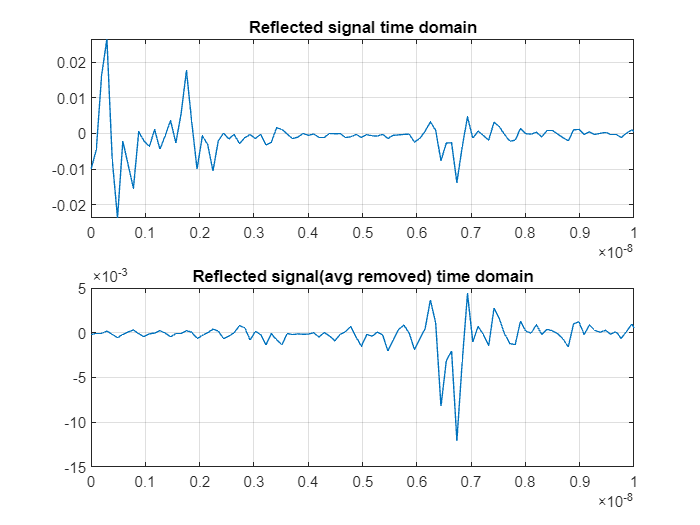

distances=(20:4:72);
data=dlmread("S scan datas\S11_72_0_CM.S1P","\t");
s=1:1:length(data);%datas to extract
freq=(data(s,1))';%freq values
re=(data(s,2))';%real part of amplitude
ima=(data(s,3))';%imaginary part of amplitude
r_wave=re+1i*ima;%combining real and imaginary
Fs=(freq(2)-freq(1))*1024;%sampling frequency
combined_re_i=zeros(1,length(freq));
combined_ima_i=zeros(1,length(freq));

for i=1:length(distances) %sum of different height points
    file_name=sprintf('S scan datas\\S11_%d_0_CM.S1P', distances(i));
    data_i=dlmread(file_name,"\t");
    re_i=(data_i(s,2))';
    combined_re_i=combined_re_i+re_i;
    ima_i=(data_i(s,3))';
    combined_ima_i=combined_ima_i+ima_i;
end

combined= combined_re_i+1i*combined_ima_i;
L=1/(length(distances));
r_wave_h= [r_wave(1)  r_wave(2:end)/2  fliplr(conj(r_wave(2:end)))/2];%Hermitian symmetry
i_r_wave=ifft(r_wave_h,1024);%ifft
t1=(0:length(i_r_wave)-1)*(1/Fs);
subplot(2,1,1)
plot(t1,real(i_r_wave));
grid on
xlim([0,10e-09]);
title('Reflected signal time domain')

%Average removal
r_wave_ar=r_wave-L*combined;%average removal
r_wave_ar_h= [r_wave_ar(1)  r_wave_ar(2:end)/2  fliplr(conj(r_wave_ar(2:end)))/2];
i_r_wave_ar_h=ifft(r_wave_ar_h,1024);
t2=(0:length(i_r_wave_ar_h)-1)*(1/Fs);
subplot(2,1,2)
plot(t2,real(i_r_wave_ar_h));
grid on
xlim([0,10e-09]);
title("Reflected signal(avg removed) time domain")